# **Live cell analysis**

Cell line: MCF10A, YFP-PCNA, NR45(pCW_Cdt1-mCherry)

Microscope: 3i 60x WI (C143) others 3i 60x Oil

Imaging:  2 min interval (C143) or 3 min interval for others

**Testing for:**

- Cdt1 degradation duration

- Cdt1 degradation relative to PCNA loading

**Annotations**

- Cdt1 degradation start

- Cdt1 low level time

- PCNA start (multiple thresholds)

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
clear S dat
%%% C143
conditions = {
        'all',1,1,1,[0 0 0]; %1   
};
dataDir = file_loc;
dat= load(['C143_data.mat'],'S');
dat = dat.S;
% dat = loadData_C143(conditions, dataDir);
dat.dataDir = file_loc;
dat.POI(:,4) = dat.filterPOI(:,5);
dat.conditions = conditions;
dat.framesPerHr = 60/2;
dat.numFrames = size(dat.area,2);
dat.xFrames = 1:dat.numFrames;
dat.xTime = (dat.xFrames-1)./dat.framesPerHr;
dat.experiment = 'C143';
S = dat;
S.POI(72,3) = S.POI(72,3) + 3;

%%% C173
conditions = {
        'all',1,1:8,1:8,[0 0 0]; %1   
};
dataDir = file_loc;
dat = load([dataDir filesep 'C173_data.mat'],'S');
dat = dat.S;
% clear dat
% dat = loadData_C173(conditions, dataDir);
dat.dataDir = dataDir;
dat.POI(:,4) = dat.filterPOI(:,10);
dat.conditions = conditions;
dat.framesPerHr = 60/3;
dat.numFrames = size(dat.area,2);
dat.xFrames = 1:dat.numFrames;
dat.xTime = (dat.xFrames-1)./dat.framesPerHr;
dat.experiment = 'C173';
S = [S dat];

%%% C175
conditions = {
        'all',1:4,1:4,1:4,[0 0 0]; %1   
};
clear dat
dataDir = file_loc;
dat = load([dataDir filesep 'C175_data.mat'],'S');
dat = dat.S;
% dat = loadData_C175(conditions, dataDir);
dat.dataDir = dataDir;
dat.POI(:,4) = dat.filterPOI(:,5);
dat.conditions = conditions;
dat.framesPerHr = 60/3;
dat.numFrames = size(dat.area,2);
dat.xFrames = 1:dat.numFrames;
dat.xTime = (dat.xFrames-1)./dat.framesPerHr;
dat.experiment = 'C175';
S = [S dat];

%%% C176
conditions = {
        'all',1:4,1:4,1:4,[0 0 0]; %1   
};
dataDir = file_loc;
dat = load([dataDir filesep 'C176_data.mat'],'S');
dat = dat.S;
% clear dat
% dat = loadData_C176(conditions, dataDir);
dat.dataDir = dataDir;
dat.POI(:,4) = dat.filterPOI(:,5);
dat.conditions = conditions;
dat.framesPerHr = 60/3;
dat.numFrames = size(dat.area,2);
dat.xFrames = 1:dat.numFrames;
dat.xTime = (dat.xFrames-1)./dat.framesPerHr;
dat.experiment = 'C176';
S = [S dat];

**Gate cells**

gates = [30 20 20 20];
filters = [5 7 5 5];
for c = 1:length(S)
    S(c).gate = false(length(S(c).area(:,1)),1);    
    for i = 1:length(S(c).area(:,1))
        if ~isnan(S(c).POI(i,3)) 
            if S(c).POI(i,3) + gates(c) <= S(c).numFrames 
                if S(c).sigNormAct(i,S(c).POI(i,3)+gates(c)) < .5 
                    S(c).gate(i) = true;
                end
            end
        end
        if S(c).POI(i,4) - 20 > 0
               pcna_pre = S(c).filterArea(i,(S(c).POI(i,4)-20):S(c).POI(i,4),filters(c));
               pcna_pre = sum(pcna_pre > 5);
                if pcna_pre >1
                    S(c).gate(i) = false;
                end
        end
    end
    disp(sprintf('%d cells left over after gate cond %d',sum(S(c).gate),c))
    
end

56 cells left over after gate cond 1
51 cells left over after gate cond 2
16 cells left over after gate cond 3
31 cells left over after gate cond 4


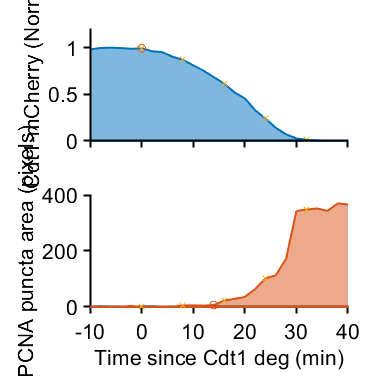

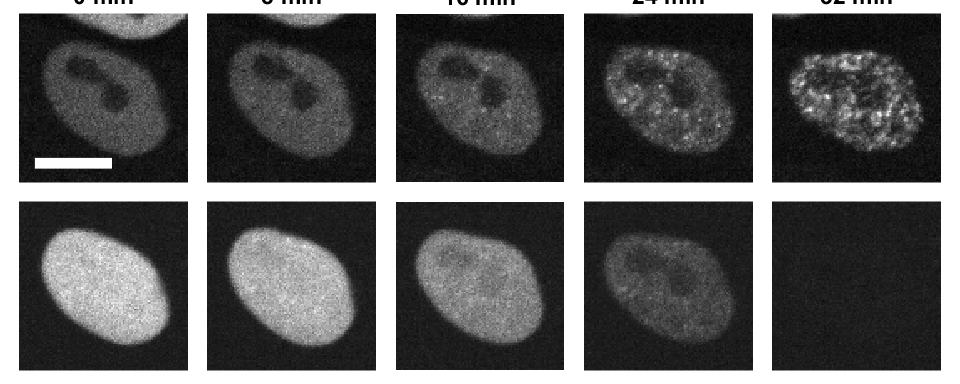

cond = 1;
rng(1)
maskpaths = {'F:\Data\C-Cdt1\Figures\Dryad\Data\C143-PCNA3i\Mask\'};
impaths = {'F:\Data\C-Cdt1\Figures\Dryad\Data\C143-PCNA3i\Raw\'};
before = 0;
after = 16;
sizeBox = 50;
interval = 4;
num_cells = 20;
pcna_filter = 5;
pcna_plot = 3;
frames = (before+after)/interval +1;
pixel = .217; % micron/pixel
bar_length = 10;

inds = S(cond).gate &  ~isnan(S(cond).POI(:,3)) & ~isnan(S(cond).filterPOI(:,pcna_filter)) &  S(cond).POI(:,3) + after <= S(cond).traceStats(:,2)...
    & S(cond).POI(:,3) - before >= S(cond).traceStats(:,1) & S(cond).sigMax >150 & S(cond).sigMax < Inf;
% cells = find(inds);
cells = 72;
% rands = randsample(length(cells),min(num_cells,length(cells)));
rands =1;
for i = 1:length(cells(rands))
    c = cells(rands(i));
    %     S(cond).POI(c,3)
%     S(cond).filterPOI(c,pcna_filter)
    cdt1_start = S(cond).POI(c,3);
    startFrame = cdt1_start - before;
    endFrame = cdt1_start + after;
    f = startFrame:interval:endFrame;
    
    cols = lines(2);
    figure('Units','inches','Position',[0 0 4 4])
    title(sprintf('Cell: %d, %d, max %.0f',cond,c,S(cond).sigMax(c)))
    tiledlayout(2,1)
    nexttile
    area(60*(S(cond).xFrames-cdt1_start)/S(cond).framesPerHr, S(cond).sigNormAct(c,:),'EdgeColor',cols(1,:),'FaceColor',cols(1,:),'FaceAlpha',.5,'LineWidth',1.5)
    hold on
    scatter(0,S(cond).sigNormAct(c,cdt1_start))
    scatter(60*(f-cdt1_start)/S(cond).framesPerHr,S(cond).sigNormAct(c,f),'x')
    ylim([0 1.2])
%     xlim(60*[min((f-cdt1_start - 4)/S(cond).framesPerHr) 2])
    xlim([-10 40])
    box off
    xticklabels([])
    xticks([-10:10:40])
    ylabel('Cdt1-mCherry (Norm)')

    nexttile
    hold on
    area(60*(S(cond).xFrames-cdt1_start)/S(cond).framesPerHr, S(cond).filterArea(c,:,pcna_plot),'EdgeColor',cols(2,:),'FaceColor',cols(2,:),'FaceAlpha',.5,'LineWidth',1.5)
    scatter(60*(S(cond).filterPOI(c,pcna_filter)-cdt1_start)/S(cond).framesPerHr,S(cond).filterArea(c,S(cond).filterPOI(c,pcna_filter),pcna_plot))
    scatter(60*(f-cdt1_start)/S(cond).framesPerHr,S(cond).filterArea(c,f,pcna_plot),'x')
    ylabel('PCNA puncta area (pixels)')
    xlabel('Time since Cdt1 deg (min)')
%     pbaspect([1 1 1])
    xticks([-10:10:40])

    xlim([-10 40])
%      print_pdf([pwd() '\Figs\' num2str(cond) '_montage_trace_cell_' num2str(c) 'final.pdf'])

%     figure('Units','inches','Position',[0 0 4 4])
%     title(sprintf('Cell: %d, %d, max %.0f',cond,c,S(cond).sigMax(c)))
%     yyaxis left
%     plot(60*(S(cond).xFrames-cdt1_start)/S(cond).framesPerHr, S(cond).sigNormAct(c,:))
%     hold on
%     scatter(0,S(cond).sigNormAct(c,cdt1_start))
%     scatter(60*(f-cdt1_start)/S(cond).framesPerHr,S(cond).sigNormAct(c,f),'x')
%     ylim([0 1.2])
% %     xlim(60*[min((f-cdt1_start - 4)/S(cond).framesPerHr) 2])
%     xlim([-10 40])
%     ylabel('Cdt1-mCherry (Norm)')
%     yyaxis right
%     
%     plot(60*(S(cond).xFrames-cdt1_start)/S(cond).framesPerHr, S(cond).filterArea(c,:,pcna_filter))
%     scatter(60*(S(cond).filterPOI(c,pcna_filter)-cdt1_start)/S(cond).framesPerHr,S(cond).filterArea(c,S(cond).filterPOI(c,pcna_filter),pcna_filter))
%     scatter(60*(f-cdt1_start)/S(cond).framesPerHr,S(cond).filterArea(c,f,pcna_filter),'x')
%     ylabel('PCNA puncta area (pixels)')
%     xlabel('Time since Cdt1 deg (min)')
%     pbaspect([1 1 1])
     print_pdf([pwd() '\Figs\' num2str(cond) '_montage_trace_cell_' num2str(c) 'final.pdf'])

    shot = S(cond).shot{c};
    im1path = [maskpaths{cond} shot '\' shot '_Mask_'];
    im2path = [impaths{cond} shot '\' shot '_YFP_'];
    im3path = [impaths{cond} shot '\' shot '_RFP_'];   
    
    f2 = figure('Units','inches','Position',[0 0 frames*2 2*2]);    

    for j=1:length(f)
        t = f(j);
        im1 = imread([im1path num2str(t) '.tif']);
        im2 = imread([im2path num2str(t) '.tif']);
        im3 = imread([im3path num2str(t) '.tif']);
        
        if cond == 1
            im2 = im2(50:4600,50:4600);
            im3 = im3(50:4600,50:4600);
        end
        
        x = S(cond).pos(c,t,1) - S(cond).jitters(c,t,1);
        y = S(cond).pos(c,t,2) - S(cond).jitters(c,t,2);

        cropx = x + [-sizeBox sizeBox];
        cropx = round(min(max(cropx,0),size(im1,1)));
        xmin = cropx(1);
        width = cropx(2) - cropx(1);
        cropy = y + [-sizeBox sizeBox];
        cropy = round(min(max(cropy,0),size(im1,2)));
        ymin=cropy(1);
        height = cropy(2) - cropy(1);
%         im1crop= imcrop(im1,[xmin ymin width height]);
        im2crop= imcrop(im2,[xmin ymin width height]);
        im3crop= imcrop(im3,[xmin ymin width height]);
        
        figure(f2)
        subplot_tight(2,frames,j,[.02 .02])
        imshow(im2crop,[80 500])
        title([num2str(60*(t-cdt1_start)/S(cond).framesPerHr) ' min'])
        if j==1
            maxval = max(im3crop(:));
            hold on
            plot([10 10 + bar_length/pixel],[90 90],'w','LineWidth',8)
        end
        subplot_tight(2,frames,j + frames,[.02 .02])
        imshow(im3crop,[50 maxval])
        
        cdt1_im = mat2gray(im3crop,[50 double(maxval)]);
        cdt1_im = cat(3,cdt1_im,cdt1_im,cdt1_im);
        
        pcna_im = mat2gray(im2crop,[80 500]);
        pcna_im = cat(3,pcna_im,pcna_im,pcna_im);        
%         
        imwrite(pcna_im, [pwd() '\Figs\ind_PCNA_' num2str(cond)  '_montage_image_' num2str(c) '_' num2str(t) '.tiff'])
        imwrite(cdt1_im, [pwd() '\Figs\ind_Cdt1_' num2str(cond)  '_montage_image_' num2str(c) '_' num2str(t) '.tiff'])

    end
   print_pdf([pwd() '\Figs\' num2str(cond)  '_montage_image_' num2str(c) 'final.pdf'])

    
end

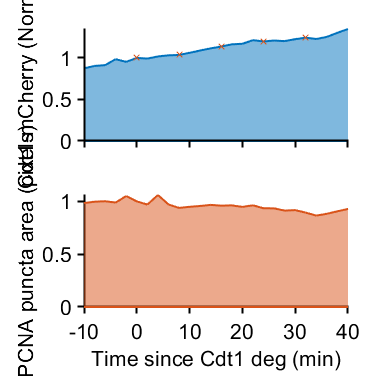

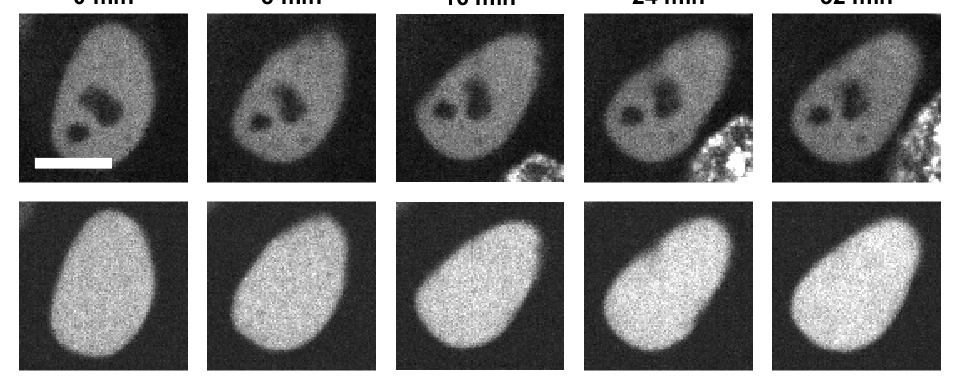

cond = 1;
rng(1)
maskpaths = {'F:\Data\C-Cdt1\Figures\Dryad\Data\C143-PCNA3i\Mask\'};
impaths = {'F:\Data\C-Cdt1\Figures\Dryad\Data\C143-PCNA3i\Raw\'};
before = 0;
after = 16;
% after = 30;
sizeBox = 50;
interval = 4;
num_cells = 4;
pcna_filter = 5;
pcna_plot = 3;
frames = (before+after)/interval +1;
pixel = .217; % micron/pixel
bar_length = 10;

compare_frame = 39;

inds =  isnan(S(cond).filterPOI(:,pcna_filter)) &  compare_frame + after <= S(cond).traceStats(:,2)...
    & compare_frame - before >= S(cond).traceStats(:,1)& S(cond).sigNuc(:,compare_frame) >150 & S(cond).pcnaNuc(:,compare_frame) > 150;
cells = find(inds);
cells = 141;
rands = randsample(length(cells),min(num_cells,length(cells)));
% rands =1;
for i = 1:length(cells(rands))
    c = cells(rands(i));

    cdt1_start =compare_frame;
    startFrame = cdt1_start - before;
    endFrame = cdt1_start + after;
    f = startFrame:interval:endFrame;
    
    cols = lines(2);
    figure('Units','inches','Position',[0 0 4 4])
    title(sprintf('Cell: %d, %d, max %.0f',cond,c,S(cond).sigMax(c)))
    tiledlayout(2,1)
    nexttile
    area(60*(S(cond).xFrames-cdt1_start)/S(cond).framesPerHr, S(cond).sigNuc(c,:)/S(cond).sigNuc(c,cdt1_start),'EdgeColor',cols(1,:),'FaceColor',cols(1,:),'FaceAlpha',.5,'LineWidth',1.5)
    hold on
%     scatter(0,S(cond).sigNuc(c,cdt1_start)/S(cond).sigNuc(c,cdt1_start))
    scatter(60*(f-cdt1_start)/S(cond).framesPerHr,S(cond).sigNuc(c,f)/S(cond).sigNuc(c,cdt1_start),'x')
%     ylim([0 1.2])
%     xlim(60*[min((f-cdt1_start - 4)/S(cond).framesPerHr) 2])
    xlim([-10 40])
    box off
    xticklabels([])
    xticks([-10:10:40])
    ylabel('Cdt1-mCherry (Norm)')

    nexttile
    hold on
    area(60*(S(cond).xFrames-cdt1_start)/S(cond).framesPerHr, S(cond).pcnaNuc(c,:)/S(cond).pcnaNuc(c,cdt1_start),'EdgeColor',cols(2,:),'FaceColor',cols(2,:),'FaceAlpha',.5,'LineWidth',1.5)
%     scatter(60*(S(cond).filterPOI(c,pcna_filter)-cdt1_start)/S(cond).framesPerHr,S(cond).filterArea(c,S(cond).filterPOI(c,pcna_filter),pcna_plot))
%     scatter(60*(f-cdt1_start)/S(cond).framesPerHr,S(cond).filterArea(c,f,pcna_plot),'x')
    ylabel('PCNA puncta area (pixels)')
    xlabel('Time since Cdt1 deg (min)')
%     pbaspect([1 1 1])
    xticks([-10:10:40])

    xlim([-10 40])
%      print_pdf([pwd() '\Figs\' num2str(cond) '_montage_trace_cell_' num2str(c) 'final.pdf'])

%     figure('Units','inches','Position',[0 0 4 4])
%     title(sprintf('Cell: %d, %d, max %.0f',cond,c,S(cond).sigMax(c)))
%     yyaxis left
%     plot(60*(S(cond).xFrames-cdt1_start)/S(cond).framesPerHr, S(cond).sigNormAct(c,:))
%     hold on
%     scatter(0,S(cond).sigNormAct(c,cdt1_start))
%     scatter(60*(f-cdt1_start)/S(cond).framesPerHr,S(cond).sigNormAct(c,f),'x')
%     ylim([0 1.2])
% %     xlim(60*[min((f-cdt1_start - 4)/S(cond).framesPerHr) 2])
%     xlim([-10 40])
%     ylabel('Cdt1-mCherry (Norm)')
%     yyaxis right
%     
%     plot(60*(S(cond).xFrames-cdt1_start)/S(cond).framesPerHr, S(cond).filterArea(c,:,pcna_filter))
%     scatter(60*(S(cond).filterPOI(c,pcna_filter)-cdt1_start)/S(cond).framesPerHr,S(cond).filterArea(c,S(cond).filterPOI(c,pcna_filter),pcna_filter))
%     scatter(60*(f-cdt1_start)/S(cond).framesPerHr,S(cond).filterArea(c,f,pcna_filter),'x')
%     ylabel('PCNA puncta area (pixels)')
%     xlabel('Time since Cdt1 deg (min)')
%     pbaspect([1 1 1])
%      print_pdf([pwd() '\Figs\' num2str(cond) '_montage_trace_cell_' num2str(c) 'final.pdf'])

    shot = S(cond).shot{c};
    im1path = [maskpaths{cond} shot '\' shot '_Mask_'];
    im2path = [impaths{cond} shot '\' shot '_YFP_'];
    im3path = [impaths{cond} shot '\' shot '_RFP_'];   
    
    f2 = figure('Units','inches','Position',[0 0 frames*2 2*2]);    

    for j=1:length(f)
        t = f(j);
        im1 = imread([im1path num2str(t) '.tif']);
        im2 = imread([im2path num2str(t) '.tif']);
        im3 = imread([im3path num2str(t) '.tif']);
        
        if cond == 1
            im2 = im2(50:4600,50:4600);
            im3 = im3(50:4600,50:4600);
        end
        
        x = S(cond).pos(c,t,1) - S(cond).jitters(c,t,1);
        y = S(cond).pos(c,t,2) - S(cond).jitters(c,t,2);

        cropx = x + [-sizeBox sizeBox];
        cropx = round(min(max(cropx,0),size(im1,1)));
        xmin = cropx(1);
        width = cropx(2) - cropx(1);
        cropy = y + [-sizeBox sizeBox];
        cropy = round(min(max(cropy,0),size(im1,2)));
        ymin=cropy(1);
        height = cropy(2) - cropy(1);
%         im1crop= imcrop(im1,[xmin ymin width height]);
        im2crop= imcrop(im2,[xmin ymin width height]);
        im3crop= imcrop(im3,[xmin ymin width height]);
        
        figure(f2)
        subplot_tight(2,frames,j,[.02 .02])
        imshow(im2crop,[80 500])
        title([num2str(60*(t-cdt1_start)/S(cond).framesPerHr) ' min'])
        if j==1
            maxval = max(im3crop(:));
            hold on
            plot([10 10 + bar_length/pixel],[90 90],'w','LineWidth',8)
        end
        subplot_tight(2,frames,j + frames,[.02 .02])
        imshow(im3crop,[50 maxval])
        
        cdt1_im = mat2gray(im3crop,[50 double(maxval)]);
        cdt1_im = cat(3,cdt1_im,cdt1_im,cdt1_im);
        
        pcna_im = mat2gray(im2crop,[80 500]);
        pcna_im = cat(3,pcna_im,pcna_im,pcna_im);        
%         
        imwrite(pcna_im, [pwd() '\Figs\ctrl_ind_PCNA_' num2str(cond)  '_montage_image_' num2str(c) '_' num2str(t) '.tiff'])
        imwrite(cdt1_im, [pwd() '\Figs\ctrl_ind_Cdt1_' num2str(cond)  '_montage_image_' num2str(c) '_' num2str(t) '.tiff'])

    end
   print_pdf([pwd() '\Figs\' num2str(cond)  '_montage_image_' num2str(c) 'final_ctrl.pdf'])

    
end

## Median CRL traces aligned to PCNA

figure('Units','inches','Position',[0 0 4 4]), hold on
conds=[1];
POI_align = 3;

for i=1:length(conds)
    c = conds(i);
    data = S(c);
    inds = data.POI(:,POI_align) < 60 & data.POI(:,POI_align) > 30 & data.sigMax > 0 & data.sigMax < 200;
    sum(inds)
    [frames, medSig, semCRL] =get_median_trace(data.sigNormAct(inds,:),data.POI(inds,POI_align));
    med_POI = median(data.POI(inds,POI_align))
    plot(60*(frames)/data.framesPerHr,medSig);
end

ans = 25

med_POI = 44

compare_frame=44;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
    inds = isnan(data.POI(:,POI_align)) & isnan(data.filterPOI(:,5)) & data.sigNuc(:,compare_frame) > 0 & data.sigNuc(:,compare_frame) < 200;
    sum(inds)
    POIs = compare_frame*ones(sum(inds),1);
    normvals = repmat(data.sigNuc(inds,compare_frame),1,size(data.sigNuc,2));
    [frames, medSig, semCRL] =get_median_trace(data.sigNuc(inds,:)./normvals,POIs);
    plot(60*(frames)/data.framesPerHr,medSig);
end

ans = 161

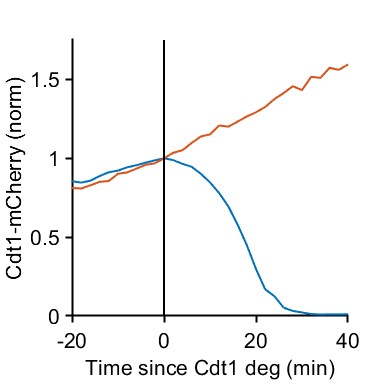

vline(0,'k')
ylabel('Cdt1-mCherry (norm)');xlabel('Time since Cdt1 deg (min)');
% legend(S.experiment);
xlim([-20 40]); 
ylim([0 1.75]);
axis square
 print_pdf([pwd() '\Figs\compare_bleach.pdf'])

## Median CRL traces aligned to PCNA

figure('Units','inches','Position',[0 0 4 4]), hold on
conds=[1];
POI_align = 3;
cols = lines(2);
for i=1:length(conds)
    c = conds(i);
    data = S(c);
    inds = data.POI(:,POI_align) < 60 & data.POI(:,POI_align) > 30 & data.sigMax > 0 & data.sigMax < 300 & data.sigMax > 30;
    sum(inds)
    [frames, medSig, semCRL] =get_mean_trace(data.sigNormAct(inds,:),data.POI(inds,POI_align),1);
    med_POI = median(data.POI(inds,POI_align))
%     plot(60*(frames)/data.framesPerHr,medSig);
   shadedErrorBar(60*(frames)/data.framesPerHr,medSig,2*semCRL,'lineProps',{'Color',cols(1,:),'LineWidth',1});

end

ans = 27

med_POI = 47

compare_frame=44;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
    inds = isnan(data.POI(:,POI_align)) & isnan(data.filterPOI(:,5)) & data.sigNuc(:,compare_frame) > 0 & data.sigNuc(:,compare_frame) < 300 & data.sigNuc(:,compare_frame) > 30;
    sum(inds)
    POIs = compare_frame*ones(sum(inds),1);
    normvals = repmat(data.sigNuc(inds,compare_frame),1,size(data.sigNuc,2));
    [frames, medSig, semCRL] =get_mean_trace(data.sigNuc(inds,:)./normvals,POIs,1);
%     plot(60*(frames)/data.framesPerHr,medSig);
   shadedErrorBar(60*(frames)/data.framesPerHr,medSig,2*semCRL,'lineProps',{'Color',cols(2,:),'LineWidth',1});
end

ans = 107

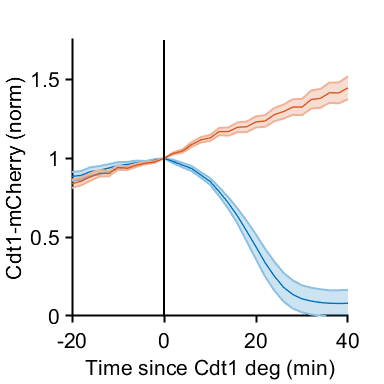

vline(0,'k')
ylabel('Cdt1-mCherry (norm)');xlabel('Time since Cdt1 deg (min)');
% legend(S.experiment);
xlim([-20 40]); 
ylim([0 1.75]);
axis square
 print_pdf([pwd() '\Figs\compare_bleach_mean.pdf'])